２次元フーリエ変換を用いて媒質の異方性主軸を同定する．

試行段階では

//Azlab-fs01/東研究室/個人work/竹内(ひ)/data/kwave/medium

にある結果を用いる．

case1のmediumを用いる．

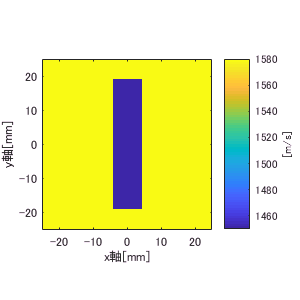

cd('//Azlab-fs01/東研究室/個人work/竹内(ひ)/data/configration')
load('transducer_2board.mat')
cd('//Azlab-fs01/東研究室/個人work/竹内(ひ)/data/kwave/medium/2018_09_04_angleScatter');
load('case1.mat')
% cd('//Azlab-fs01/東研究室/個人work/竹内(ひ)/data/kwave/medium/2018_08_10_realisticScatter');
% load('case1.mat')
figure;
imagesc(kgrid.x_vec*1000,kgrid.y_vec*1000,medium.sound_speed);
xlabel('x軸[mm]')
ylabel('y軸[mm]')
colorbar;
caxis([1450 1580]);
c = colorbar;
c.Label.String = '[m/s]';
ax = gca;
ax.YDir = 'normal';
axis equal
axis tight
myfilename = sprintf('//Azlab-fs01/東研究室/個人work/竹内(ひ)/result/2018_09_04_2D_FFT/angle_case1_SSdist');
exportfig(myfilename,'png',[300,300]);

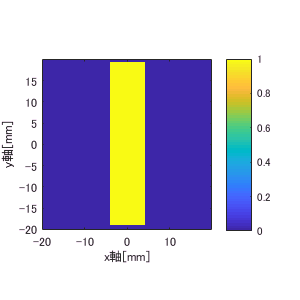

tmp = medium.sound_speed(51:450,51:450);
binary_medium = (tmp == min(min(tmp)));
imagesc(kgrid.x_vec(51:450)*1000,kgrid.y_vec(51:450)*1000,binary_medium);
colorbar;
axis equal
axis tight
xlabel('x軸[mm]')
ylabel('y軸[mm]')
ax = gca;
ax.YDir = 'normal';
myfilename = sprintf('//Azlab-fs01/東研究室/個人work/竹内(ひ)/result/2018_09_04_2D_FFT/angle_case1_binalize');
exportfig(myfilename,'png',[300,300]);

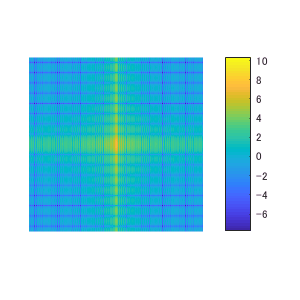

fft2_binary_medium = fft2(binary_medium);
figure;
imagesc(log(abs(fftshift(fft2_binary_medium))));
colorbar;
ax = gca;
ax.YDir = 'normal';
xlabel('水平周波数')
ylabel('垂直周波数')
axis equal
axis tight
axis off
myfilename = sprintf('//Azlab-fs01/東研究室/個人work/竹内(ひ)/result/2018_09_04_2D_FFT/angle_case1_fft_log');
exportfig(myfilename,'png',[300,300]);

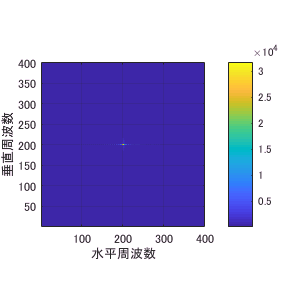

fft2_binary_medium = fft2(binary_medium);
figure;
imagesc(abs(fftshift(fft2_binary_medium)));
colorbar;
ax = gca;
ax.YDir = 'normal';
xlabel('水平周波数')
ylabel('垂直周波数')
axis equal
axis tight
grid on
myfilename = sprintf('//Azlab-fs01/東研究室/個人work/竹内(ひ)/result/2018_09_04_2D_FFT/angle_case1_fft_abs');
exportfig(myfilename,'png',[300,300]);

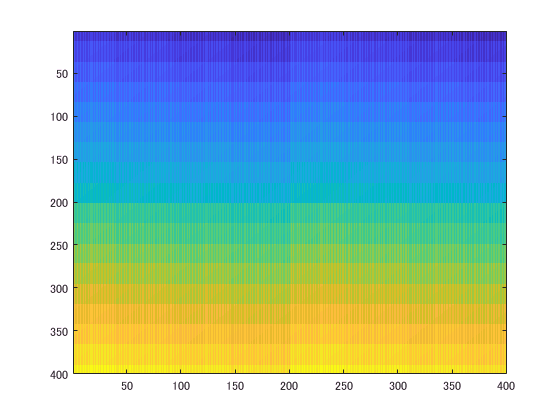

a = unwrap(angle(fftshift(fft2_binary_medium)));
figure;
imagesc(a);

FFT = abs(fftshift(fft2_binary_medium));
[leng_y,leng_x] = size(FFT);
x_vec = kgrid.x_vec(51:450);
y_vec = kgrid.y_vec(51:450);
theta = zeros(leng_y,leng_x);
rho = zeros(leng_y,leng_x);
for i = 1:leng_y
    for j = 1:leng_x
        [theta(i,j),rho(i,j)] = cart2pol(x_vec(j)*1000,y_vec(i)*1000);
        if theta(i,j) < 0
            theta(i,j) = theta(i,j) + 2*pi;
        end
    end
end

位相プロット，振幅プロットの妥当性を確認．

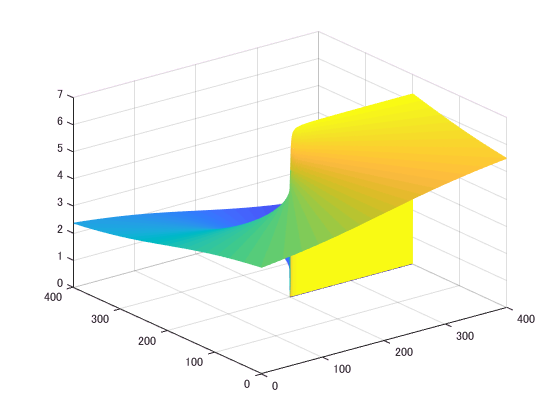

figure;mesh(theta);

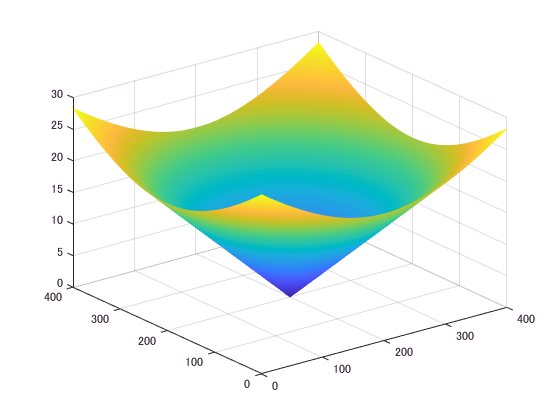

figure;mesh(rho);

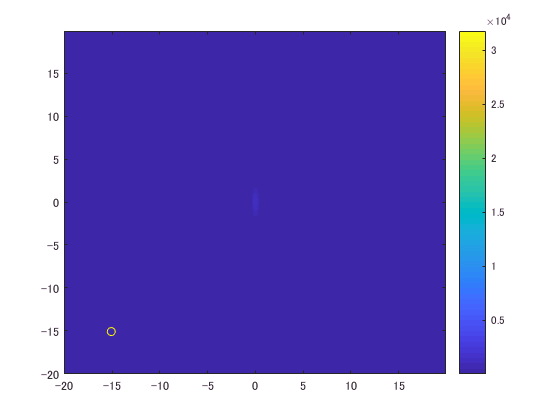

figure;imagesc(y_vec*1000,x_vec*1000,FFT);
colorbar;
ax = gca;
ax.YDir = 'normal';
hold on
scatter(x_vec(50)*1000,y_vec(50)*1000,'y')

theta(50,50)/pi

ans = 1.2500

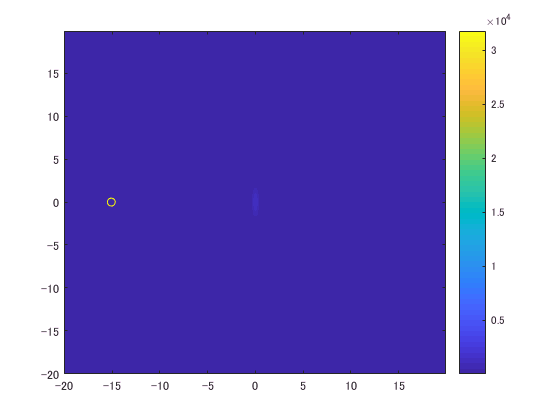

figure;imagesc(y_vec*1000,x_vec*1000,FFT);
colorbar;
ax = gca;
ax.YDir = 'normal';
hold on
scatter(x_vec(50)*1000,y_vec(201)*1000,'y')

theta(201,50)/pi

ans = 1

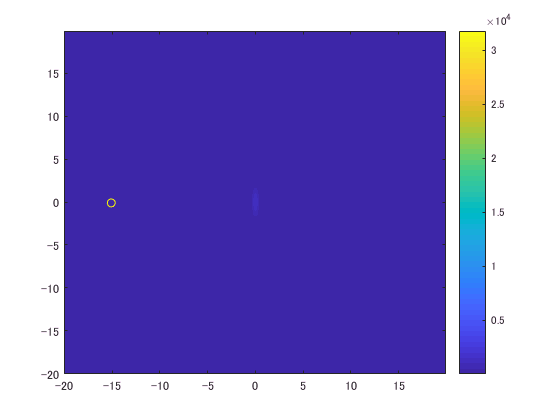

figure;imagesc(y_vec*1000,x_vec*1000,FFT);
colorbar;
ax = gca;
ax.YDir = 'normal';
hold on
scatter(x_vec(50)*1000,y_vec(200)*1000,'y')

theta(200,50)/pi

ans = 1.0021

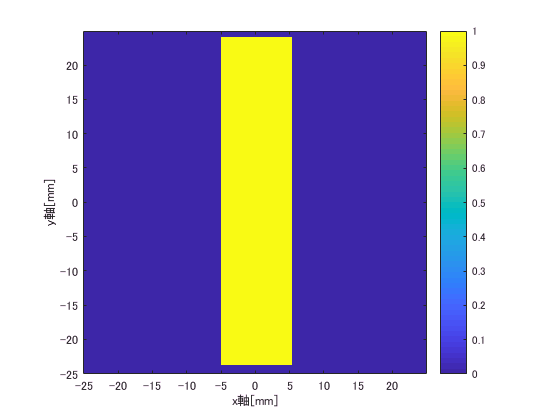

figure;
imagesc(kgrid.x_vec*1000,kgrid.y_vec*1000,binary_medium);
colorbar;
axis equal
axis tight
xlabel('x軸[mm]')
ylabel('y軸[mm]')
ax = gca;
ax.YDir = 'normal';

スペクトル分布を作成する．

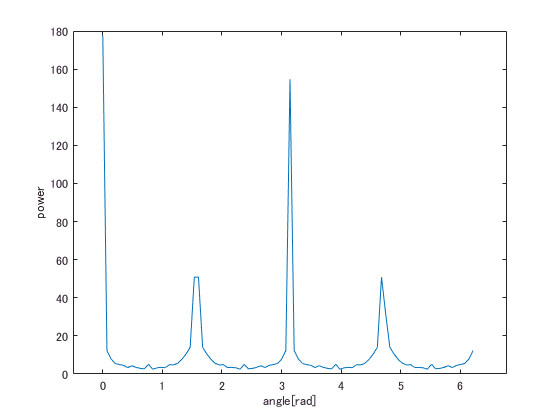

interval_num = 90;
reference_angle = linspace(0, ((interval_num-1)/interval_num)*2*pi, interval_num)';
d_theta = pi/interval_num;
spectrum_distribution = zeros(interval_num,1);
scan_domain = zeros(400,400,interval_num);
target_rho = (rho<=min(max(x_vec)*1000,max(y_vec)*1000));
target_theta = ((2*pi-d_theta<=theta)&(theta<=2*pi))|((0<=theta)&(theta<d_theta));
scan_domain(:,:,1) = target_rho.*target_theta;
spectrum_distribution(1,1) = sum(sum(scan_domain(:,:,1).*FFT))/(sum(sum(scan_domain(:,:,1))));


for ii = 2:interval_num
    target_theta = (reference_angle(ii,1)-d_theta<theta)&(theta<=reference_angle(ii,1)+d_theta);
     scan_domain(:,:,ii) = target_rho.*target_theta;
    spectrum_distribution(ii,1) = sum(sum(scan_domain(:,:,ii).*FFT))/(sum(sum(scan_domain(:,:,ii))));
   
end

figure;
plot(reference_angle,spectrum_distribution);
xlabel('angle[rad]')
ylabel('power')
xlim([-0.5,2*pi+0.5])

説明用のフィギュア作成

clear mov
fr(1:interval_num) = struct('cdata',[],'colormap',[])

fr = フィールドをもつ 1×90 の struct 配列:
    cdata
    colormap


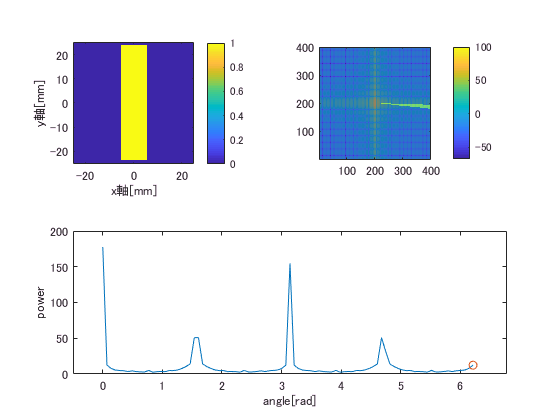

figure(1);
% make movie
for i=1:interval_num
    subplot(2,2,1);
    imagesc(kgrid.x_vec*1000,kgrid.y_vec*1000,binary_medium);
    colorbar;
    axis equal
    axis tight
    xlabel('x軸[mm]')
    ylabel('y軸[mm]')
    ax = gca;
    ax.YDir = 'normal';
    subplot(2,2,2);
    imagesc(20*log10(abs(FFT)));
    axis equal
    axis tight
    ax = gca;
    ax.YDir = 'normal';
    hold on
    image(100*scan_domain(:,:,i),'AlphaData',0.4);
    colorbar;
    subplot(2,2,[3,4]);
    plot(reference_angle(1:i),spectrum_distribution(1:i));
    hold on
    scatter(reference_angle(i),spectrum_distribution(i));
    xlabel('angle[rad]')
    ylabel('power')
    xlim([-0.5,2*pi+0.5])
    pause(0.05);
    hold off
    drawnow;
    fr(i) = getframe(1);
end

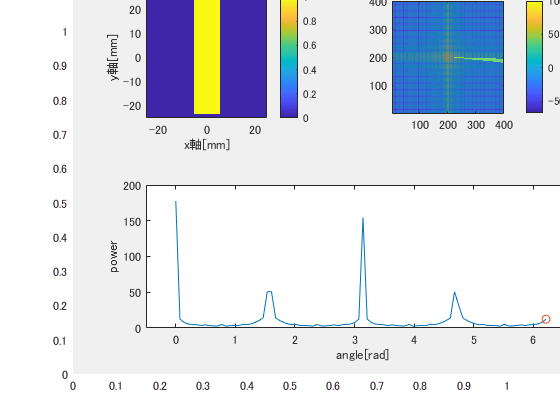

% play movie
figure;
movie(fr)

% save movie
cd('//Azlab-fs01/東研究室/個人work/竹内(ひ)/result/2018_09_04_2D_FFT')
mv = VideoWriter('2018_09_18_sample_fft','MPEG-4');
mv.FrameRate = 10; % ← fpsと同じ %ART:3
open(mv)
writeVideo(mv,fr)
close(mv)

主方向角度決定

[max_spectrum,ind_spectrum] = max(spectrum_distribution);
major_angle = reference_angle(ind_spectrum);